% Author: Guo Long
% Date: 2024-10-20
% Location: Lee Shaukee Buliding, Tsinghua university,Beijing, China.
% contact me: guol22@mails.tsinghua.edu.cn
% Description:
% The primary objective of this code is to generate and visualize the optimization results 
% presented in Section 3.2.3, which include trajectory planning for a Stephenson-I 
% six-bar mechanism (part 1), kinematic analysis (part 2), parameter calculation for 
% the trajectory (part 3), and plotting the corresponding figures (part 4). 
% Matlab 2020b

clear,clc,close all
%...Part1:Composite Cycloid Trajectory Planning
    clear,clc
    t = [0:pi/499:pi];
    S = 300;
    H = 100;
    T = pi;
    x1 = S*(t/T-1/(2*pi)*sin(2*pi*t/T));
    y1 = -H*(1/2-1/2*cos(2*pi*t/T));
    l = length(x1)

l = 500

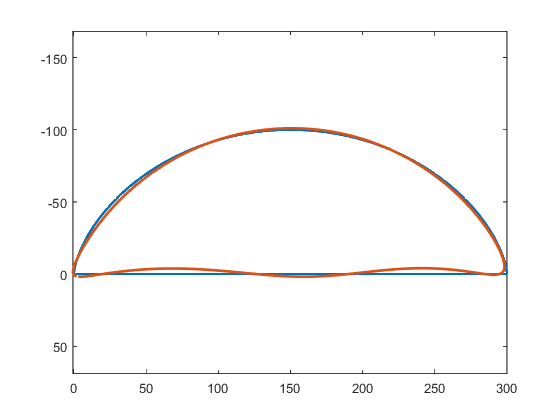

    x2 = x1(end):-(x1(end)-x1(1))/l:x1(1);
    x2(end) = [];
    y2 = zeros(1,l);
    xh_t = [x1,x2];
    yh_t = [y1,y2];    
    figure(1)
    plot(xh_t,yh_t,'linewidth',2);hold on  

%...Part2: 运动学计算
    X_opt = zusers_read_txt_row('result_3th_opt.txt',200);  % Read the optimization results from section 3.2.3
    X_opt = sortrows(X_opt,17);
    index = 185;   % This individual is good
    x_opt = X_opt(index,1:16);
    [xh,yh,MSE] =  kinematics(x_opt,'ste1',360); 

%...Part3: Calculate trajectory parameters
    [index1,index2,h3,theta1,imp1,S] = get_parameters(xh,yh);
    
    plot(xh(1:2:end),yh(1:2:end),'linewidth',2),axis equal;set(gca,'YDir','reverse');

    para_opt_3th.h3 = h3;
    para_opt_3th.imp1 = imp1;
    para_opt_3th.MSE = MSE;
    para_opt_3th.S = S

para_opt_3th = 包含以下字段的 struct :
      h3: 5.8886
    imp1: 0.9115
     MSE: 3.9773
       S: 0.0196


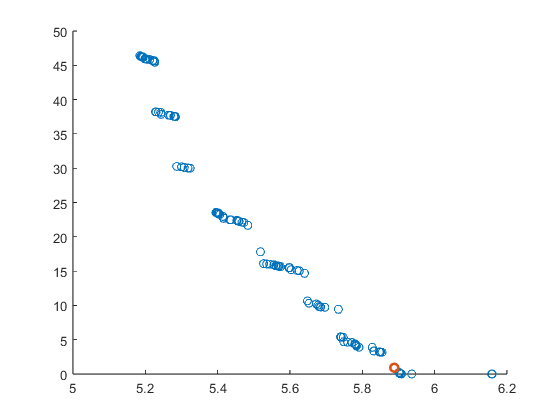

    x_opt_3th = x_opt;
    
%...Part4:Draw an individual distribution map
    %...Draw the optimized trajectory
    f1 = X_opt(:,17);
    f2 = X_opt(:,18);       
    figure(2); scatter(f1,f2);  hold on
    scatter(f1(index),f2(index),'linewidth',2)

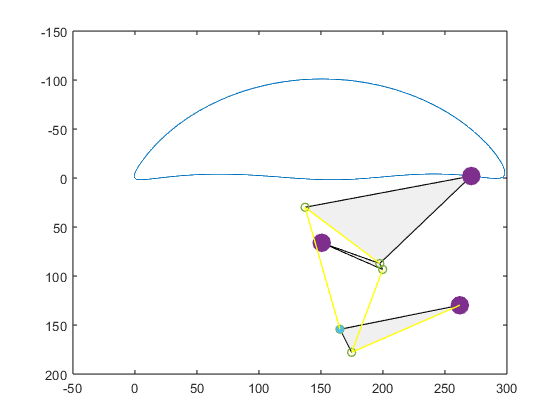

    %...Draw the schematic diagram of the mechanism
    x_opt_3th(16) = deg2rad(30);
    figure(3)
    [xh_nsga,yh_nsga,MSE,x,y] = kinematics(x_opt_3th,'ste1',360);    
    [index1,index2,h3,theta1,imp1] = get_parameters(xh_nsga,yh_nsga);
    plot(xh_nsga,yh_nsga);     hold on;    
    set (gca,'YDir','reverse')
    scatter(x,y); 
    xa = x(1); ya = y(1);
    xb = x(2); yb = y(2);
    xc = x(3); yc = y(3);
    xd = x(4); yd = y(4);
    xe = x(5); ye = y(5);
    xf = x(6); yf = y(6);
    xg = x(7); yg = y(7);
    xh = x(8); yh = y(8);
    %...triangle
    xpitch = [xe ; xh ; xf];
    ypitch = [ye ; yh ; yf];
    patch(xpitch,ypitch,[0.94 0.94 0.94],'edgecolor',[0 0 0])   
    xpitch = [xc ; xg ; xd];
    ypitch = [yc ; yg ; yd];
    patch(xpitch,ypitch,[0.94 0.94 0.94],'edgecolor',[0 0 0]) 
    xpitch = [xa ; xb ; xe];hold on
    ypitch = [ya ; yb ; ye];
    patch(xpitch,ypitch,[0.94 0.94 0.94],'edgecolor',[0 0 0]);hold on;
    %...points
    scatter(xg,yg,'linewidth',1)
    scatter([xa,xd,xh],[ya,yd,yh],'linewidth',8);
    scatter([xb,xc,xe,xf,xg],[yb,yc,ye,yf,yg],'linewidth',1);
    scatter(xg,yg,'filled')
    %...links
    plot([xb,xc,xd],[yb,yc,yd],'yellow','linewidth',1)
    plot([xe,xf,xg],[ye,yf,yg],'yellow','linewidth',1)